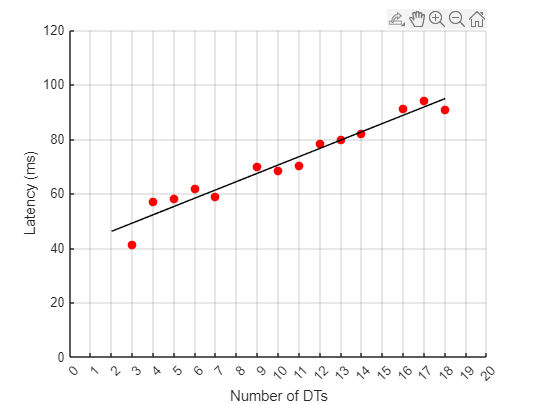

DT_Agg = readmatrix("DT_Aggregate_Single_Data_Cleaned.csv");
for c = 1:DT_Agg

end
scatter(DT_Agg(:,23),DT_Agg(:,24),'red','o','MarkerFaceColor','flat');
h = lsline;
set(h(1),'color','k')
ylim([0 120])
xlim([0 20])
xlabel('Number of DTs')
ylabel('Latency (ms)')
%title('Latency vs Number of DTs')
xticks([linspace(0,20,21)])
grid on

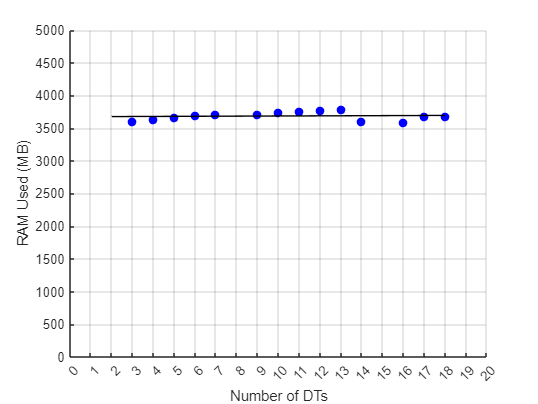


DT_Agg = readmatrix("DT_Aggregate_Single_Data_Cleaned.csv");
scatter(DT_Agg(:,23),DT_Agg(:,25),'blue','o','MarkerFaceColor','flat');
h = lsline;
set(h(1),'color','k')
ylim([0 5000])
xlim([0 20])
xlabel('Number of DTs')
ylabel('RAM Used (MB)')
%title('RAM Used vs Number of DTs')
xticks([linspace(0,20,21)])
grid on

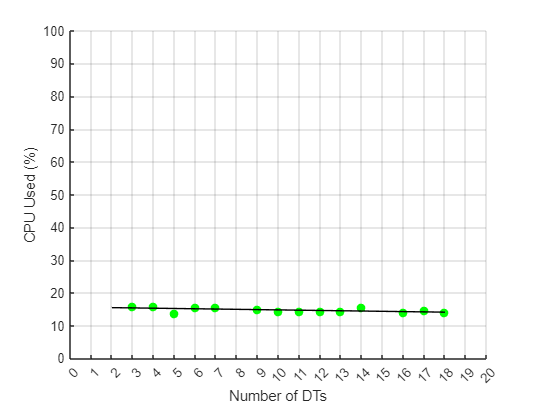


DT_Agg = readmatrix("DT_Aggregate_Single_Data_Cleaned.csv");
scatter(DT_Agg(:,23),DT_Agg(:,26),'green','o','MarkerFaceColor','flat');
h = lsline;
set(h(1),'color','k')
ylim([0 100])
xlim([0 20])
xlabel('Number of DTs')
ylabel('CPU Used (%)')
%title('CPU Used vs Number of DTs')
xticks([linspace(0,20,21)])
grid on


%{
DT_Agg_Multi_Date = readmatrix("DT_Aggregate_Multiple_Data.csv");
scatter3(DT_Agg_Multi_Date(:,1),DT_Agg_Multi_Date(:,5),DT_Agg_Multi_Date(:,20)), hold on

Conv_Agg_Multi_Date = readmatrix("Conv_Aggregate_Multiple_Data.csv");
scatter3(Conv_Agg_Multi_Date(:,1),Conv_Agg_Multi_Date(:,5),Conv_Agg_Multi_Date(:,11))
%zlim([0 5000])
%}

%{
DT_Single_DTI_Single = readmatrix("DT_Single_DTI_Single_Data.csv");
boxplot(DT_Single_DTI_Single(:,6)), hold on

Conv_Single_DTI_Single = readmatrix("Conv_Single_DTI_Single_Data_File.csv");
boxplot(Conv_Single_DTI_Single(:,6))
%}

%{
DT_Multiple_DTI_Single = readmatrix("DT_Multiple_DTI_Single_Data.csv");
scatter(DT_Multiple_DTI_Single(:,4),DT_Multiple_DTI_Single(:,9), 'filled','o'), hold on
%set(gca, 'yscale','log'), hold on
lsline
%semilogy(DT_Multiple_DTI_Single(:,4),DT_Multiple_DTI_Single(:,6)), hold on

Conv_Multiple_DTI_Single = readmatrix("Conv_Multiple_DTI_Single_Data.csv");
scatter(Conv_Multiple_DTI_Single(:,4),Conv_Multiple_DTI_Single(:,9), 'filled','o')
%set(gca, 'yscale','log')
lsline
legend('DT Total Ram', 'LOB','Conv Total Ram', 'LOB')
ylim([0 3500])
%semilogy(Conv_Multiple_DTI_Single(:,4),Conv_Multiple_DTI_Single(:,6))
%}

%{
DT_Agg_Multiple = readmatrix("DT_Aggregate_Multiple_Data.csv");
scatter(DT_Agg_Multiple(:,4),DT_Agg_Multiple(:,9), 'filled','o'), hold on
%set(gca, 'yscale','log'), hold on
lsline
%semilogy(DT_Multiple_DTI_Single(:,4),DT_Multiple_DTI_Single(:,6)), hold on

Conv_Agg_Multiple = readmatrix("Conv_Aggregate_Multiple_Data.csv");
scatter(Conv_Agg_Multiple(:,4),Conv_Agg_Multiple(:,9), 'filled','o')
%set(gca, 'yscale','log')
lsline
legend('DT Total Ram', 'LOB','Conv Total Ram', 'LOB')
ylim([0 4000])
%}